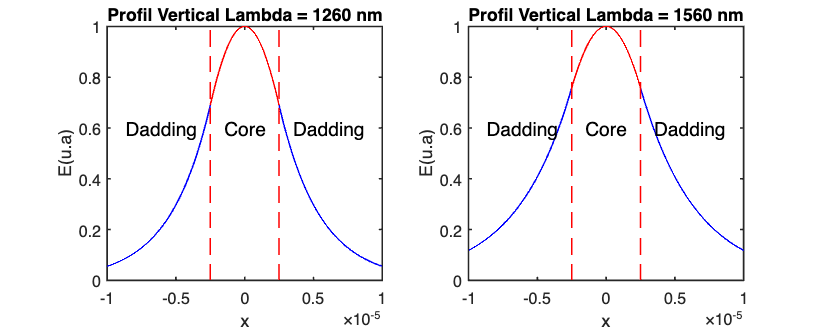

% Étude de cas OOG

% Génération d'une séquence de valeurs pour x allant de -10 à 10 micromètres avec 501 points
x = linspace(-10e-6, 10e-6, 501);

% Définition des variables
n1 = 1.463; % Indice de réfraction du matériau 1
n2 = 1.460; % Indice de réfraction du matériau 2
lambda1 = 1260e-9; % Longueur d'onde en mètres pour lambda1
lambda2 = 1560e-9; % Longueur d'onde en mètres pour lambda2
n_effh1 = 1.46156; % Indice de réfraction effectif pour lambda1
n_effh2 = 1.46130; % Indice de réfraction effectif pour lambda2

% Profil Horizontal

% Dans le noyau (Core)
b = 5e-6; % Taille du noyau en mètres
x_core = linspace(-b/2, b/2, 501); % Génération de valeurs pour x dans le noyau

% Calcul des expressions pour lambda1 dans le noyau
alpha_h1260 = sqrt((n1)^2 * (2*pi/lambda1)^2 - ((2*pi/lambda1)*n_effh1)^2);
E_core1_h = cos(alpha_h1260 * x_core); % Distribution d'amplitude électrique normalisée à 1

% Calcul des expressions pour lambda2 dans le noyau
alpha_h1560 = sqrt((n1)^2 * (2*pi/lambda2)^2 - ((2*pi/lambda2)*n_effh2)^2);
E_core2_h = cos(alpha_h1560 * x_core); % Distribution d'amplitude électrique normalisée à 1

% Dans le revêtement (Dadding)
x_dadding = linspace(b/2, 10e-6, 501); % Génération de valeurs pour x dans le revêtement

% Calcul des expressions pour lambda1 dans le revêtement
kappa_h1260 = sqrt(((2*pi/lambda1)*n_effh1)^2 - (n2)^2*(2*pi/lambda1)^2);
E_dadding1_h = cos(alpha_h1260*b/2)*exp(kappa_h1260*b/2) * exp(-kappa_h1260*abs(x_dadding));

% Calcul des expressions pour lambda2 dans le revêtement
kappa_h1560 = sqrt(((2*pi/lambda2)*n_effh2)^2 - (n2)^2*(2*pi/lambda2)^2);
E_dadding2_h = cos(alpha_h1560*b/2)* exp(kappa_h1560*b/2) * exp(-kappa_h1560*abs(x_dadding));


% Affichage des graphiques
fig = figure('Position', [100, 100, 1000, 400]); % Définition de la taille de la figure

subplot(1, 2, 1)
plot(x_core, E_core1_h, x_dadding, E_dadding1_h,'b', -x_dadding, E_dadding1_h,'b' )
hold on
% Barres verticales délimitant le noyau
line([-b/2, -b/2], [0, 1], 'Color', 'r', 'LineStyle', '--');
line([b/2, b/2], [0, 1], 'Color', 'r', 'LineStyle', '--');
% Annotations
text(0, 0.6, 'Core', 'HorizontalAlignment', 'center', 'VerticalAlignment', 'middle', 'FontSize', 12)
text(-b/2 - 1e-6, 0.6, 'Dadding', 'HorizontalAlignment', 'right', 'VerticalAlignment', 'middle', 'FontSize', 12)
text(b/2 + 1e-6, 0.6, 'Dadding', 'HorizontalAlignment', 'left', 'VerticalAlignment', 'middle', 'FontSize', 12)
hold off
title('Profil Vertical Lambda = 1260 nm')
xlabel('x')
ylabel('E(u.a)')
xlim([-10e-6, 10e-6]) % Définition des limites de l'axe des x

subplot(1, 2, 2)
plot(x_core, E_core2_h, x_dadding, E_dadding2_h,'b', -x_dadding, E_dadding2_h,'b')
hold on
% Barres verticales délimitant le noyau
line([-b/2, -b/2], [0, 1], 'Color', 'r', 'LineStyle', '--');
line([b/2, b/2], [0, 1], 'Color', 'r', 'LineStyle', '--');
% Annotations
text(0, 0.6, 'Core', 'HorizontalAlignment', 'center', 'VerticalAlignment', 'middle', 'FontSize', 12)
text(-b/2 - 1e-6, 0.6, 'Dadding', 'HorizontalAlignment', 'right', 'VerticalAlignment', 'middle', 'FontSize', 12)
text(b/2 + 1e-6, 0.6, 'Dadding', 'HorizontalAlignment', 'left', 'VerticalAlignment', 'middle', 'FontSize', 12)
hold off
title('Profil Vertical Lambda = 1560 nm')
xlabel('x')
ylabel('E(u.a)')
xlim([-10e-6, 10e-6]) % Définition des limites de l'axe des x

% Changer le nom de la figure
set(fig, 'Name', 'Profil Horizontal');

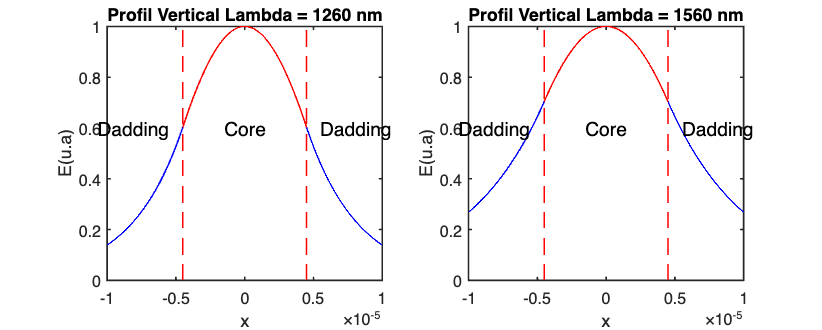


%% 

% Profil Vertical

n_effv1 = 1.46098;
n_effv2 = 1.46065 ; 
% Dans le noyau (Core)
a = 9e-6; % Taille du noyau en mètres
x_core = linspace(-a/2, a/2, 501); % Génération de valeurs pour x dans le noyau

% Calcul des expressions pour lambda1 dans le noyau
alpha_1260_v = sqrt((n_effh1)^2 * (2*pi/lambda1)^2 - ((2*pi/lambda1)*n_effv1)^2);
E_core1_v = cos(alpha_1260_v * x_core); % Distribution d'amplitude électrique normalisée à 1

% Calcul des expressions pour lambda2 dans le noyau
alpha_1560_v = sqrt((n_effh2)^2 * (2*pi/lambda2)^2 - ((2*pi/lambda2)*n_effv2 )^2);
E_core2_v = cos(alpha_1560_v * x_core); % Distribution d'amplitude électrique normalisée à 1

% Dans le revêtement (Dadding)
x_dadding = linspace(a/2, 10e-6, 501); % Génération de valeurs pour x dans le revêtement

% Calcul des expressions pour lambda1 dans le revêtement
kappa_h1260 = sqrt(((2*pi/lambda1)*n_effv1)^2 - (n2)^2*(2*pi/lambda1)^2);
E_dadding1_v = cos(alpha_1260_v*a/2)*exp(kappa_h1260*a/2) * exp(-kappa_h1260*abs(x_dadding));

% Calcul des expressions pour lambda2 dans le revêtement
kappa_h1560 = sqrt(((2*pi/lambda2)*n_effv2 )^2 - (n2)^2*(2*pi/lambda2)^2);
E_dadding2 = cos(alpha_1560_v*a/2)* exp(kappa_h1560*a/2) * exp(-kappa_h1560*abs(x_dadding));


% Affichage des graphiques
fig = figure('Position', [100, 100, 1000, 400]); % Définition de la taille de la figure

subplot(1, 2, 1)
plot(x_core, E_core1_v, x_dadding, E_dadding1_v,'b', -x_dadding, E_dadding1_v,'b' )
hold on
% Barres verticales délimitant le noyau
line([-a/2, -a/2], [0, 1], 'Color', 'r', 'LineStyle', '--');
line([a/2, a/2], [0, 1], 'Color', 'r', 'LineStyle', '--');
% Annotations
text(0, 0.6, 'Core', 'HorizontalAlignment', 'center', 'VerticalAlignment', 'middle', 'FontSize', 12)
text(-a/2 - 1e-6, 0.6, 'Dadding', 'HorizontalAlignment', 'right', 'VerticalAlignment', 'middle', 'FontSize', 12)
text(a/2 + 1e-6, 0.6, 'Dadding', 'HorizontalAlignment', 'left', 'VerticalAlignment', 'middle', 'FontSize', 12)
hold off
title('Profil Vertical Lambda = 1260 nm')
xlabel('x')
ylabel('E(u.a)')
xlim([-10e-6, 10e-6]) % Définition des limites de l'axe des x

subplot(1, 2, 2)
plot(x_core, E_core2_v, x_dadding, E_dadding2,'b', -x_dadding, E_dadding2,'b')
hold on
% Barres verticales délimitant le noyau
line([-a/2, -a/2], [0, 1], 'Color', 'r', 'LineStyle', '--');
line([a/2, a/2], [0, 1], 'Color', 'r', 'LineStyle', '--');
% Annotations
text(0, 0.6, 'Core', 'HorizontalAlignment', 'center', 'VerticalAlignment', 'middle', 'FontSize', 12)
text(-a/2 - 1e-6, 0.6, 'Dadding', 'HorizontalAlignment', 'right', 'VerticalAlignment', 'middle', 'FontSize', 12)
text(a/2 + 1e-6, 0.6, 'Dadding', 'HorizontalAlignment', 'left', 'VerticalAlignment', 'middle', 'FontSize', 12)
hold off
title('Profil Vertical Lambda = 1560 nm')
xlabel('x')
ylabel('E(u.a)')
xlim([-10e-6, 10e-6]) % Définition des limites de l'axe des x

% Changer le nom de la figure
set(fig, 'Name', 'Profil Vertical');

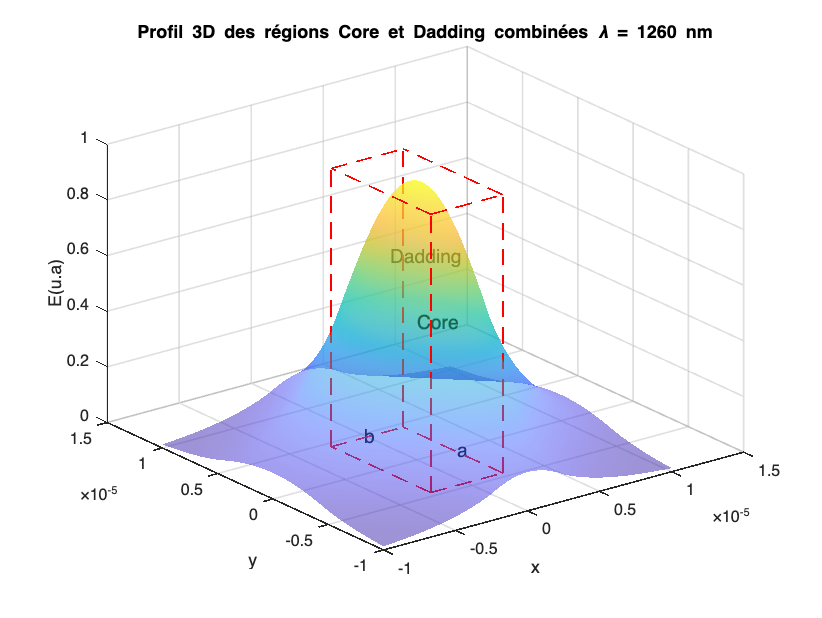



%%

%%% LA VICTOIRE %%%

% POUR LAMBDA1

% Génération de la grille 3D
[X, Y] = meshgrid(x, x);

% Initialisation de Z avec des zéros
Z1= zeros(size(X));

% Conditions pour les régions Core, Dadding et chevauchantes
L_core = (abs(X) < b/2 & abs(Y) < a/2);
L_dadding_X1 = (abs(X) >= b/2 & abs(Y) < a/2);
L_dadding_X2 = (abs(X) >= b/2 & abs(Y) > a/2);
L_dadding_Y1 = (abs(Y) >= a/2 & abs(X) < b/2);
L_dadding_Y2 = (abs(Y) >= a/2 & abs(X) > b/2);

% Attribution des valeurs en fonction des conditions pour la région Core
Z1(L_core) = cos(alpha_h1260 * X(L_core)) .* cos(alpha_1260_v * Y(L_core));

% Calcul des valeurs pour la région Dadding en quatre parties
Z_dadding_X1 = cos(alpha_h1260*b/2)*exp(kappa_h1260*b/2) .* exp(-kappa_h1260*abs(X(L_dadding_X1))) .* cos(alpha_1260_v * Y(L_dadding_X1));
Z_dadding_X2 = cos(alpha_h1260*b/2)*exp(kappa_h1260*b/2) .* exp(-kappa_h1260*abs(X(L_dadding_X2))) .*cos(alpha_1260_v*a/2)* exp(kappa_h1260*a/2) .* exp(-kappa_h1260*abs(Y(L_dadding_X2)));


Z_dadding_Y1 = cos(alpha_1260_v*a/2)*exp(kappa_h1260*a/2) .* exp(-kappa_h1260*abs(Y(L_dadding_Y1))) .* cos(alpha_h1260 * X(L_dadding_Y1));
Z_dadding_Y2 = cos(alpha_1260_v*a/2)*exp(kappa_h1260*a/2) .* exp(-kappa_h1260*abs(Y(L_dadding_Y2))) .*cos(alpha_h1260*b/2)*exp(kappa_h1260*b/2) .* exp(-kappa_h1260*abs(X(L_dadding_Y2)));

% Attribution des valeurs calculées aux régions correspondantes
Z1(L_dadding_X1) = Z_dadding_X1;
Z1(L_dadding_X2) = Z_dadding_X2;
Z1(L_dadding_Y1) = Z_dadding_Y1;
Z1(L_dadding_Y2) = Z_dadding_Y2;

% Affichage de Z(L1) et Z(L2) combinés
figure;
surf(X, Y, Z1, 'FaceAlpha', 0.5, 'EdgeColor', 'none');
% Ajout du titre
title('Profil 3D des régions Core et Dadding combinées \lambda = 1260 nm');

% Ajout des étiquettes d'axe
xlabel('x');
ylabel('y');
zlabel('E(u.a)');

% Affichage du texte "Core" dans la zone Core
text(0, 0, 0.5, 'Core', 'FontSize', 12, 'Color', 'black');

% Affichage du texte "Dadding" dans la zone Dadding
text(b, a, 0.5, 'Dadding', 'FontSize', 12, 'Color', 'black');

% Affichage du côté a 
text(b/2+0.3e-6, 0, 0, 'a', 'FontSize', 12, 'Color', 'black');

% Affichage du côté b
text(0, a/2+0.3e-6, 0, 'b', 'FontSize', 12, 'Color', 'black');

% Ajout des lignes en pointillés pour délimiter la zone du core
hold on;


line([-b/2, -b/2], [-a/2, -a/2], [0, 1], 'Color', 'red', 'LineStyle', '--');
line([b/2, b/2], [-a/2, -a/2], [0, 1], 'Color', 'red', 'LineStyle', '--');
line([-b/2, -b/2], [a/2, a/2], [0, 1], 'Color', 'red', 'LineStyle', '--');
line([b/2, b/2], [a/2, a/2], [0, 1], 'Color', 'red', 'LineStyle', '--');

line([-b/2, -b/2], [-a/2, a/2], [1, 1], 'Color', 'red', 'LineStyle', '--');
line([b/2, b/2], [-a/2, a/2], [1, 1], 'Color', 'red', 'LineStyle', '--');
line([-b/2, b/2], [-a/2, -a/2], [1, 1], 'Color', 'red', 'LineStyle', '--');
line([-b/2, b/2], [a/2, a/2], [1, 1], 'Color', 'red', 'LineStyle', '--');

line([-b/2, -b/2], [-a/2, a/2], [0, 0], 'Color', 'red', 'LineStyle', '--');
line([b/2, b/2], [-a/2, a/2], [0, 0], 'Color', 'red', 'LineStyle', '--');
line([-b/2, b/2], [-a/2, -a/2], [0, 0], 'Color', 'red', 'LineStyle', '--');
line([-b/2, b/2], [a/2, a/2], [0, 0], 'Color', 'red', 'LineStyle', '--');
hold off;

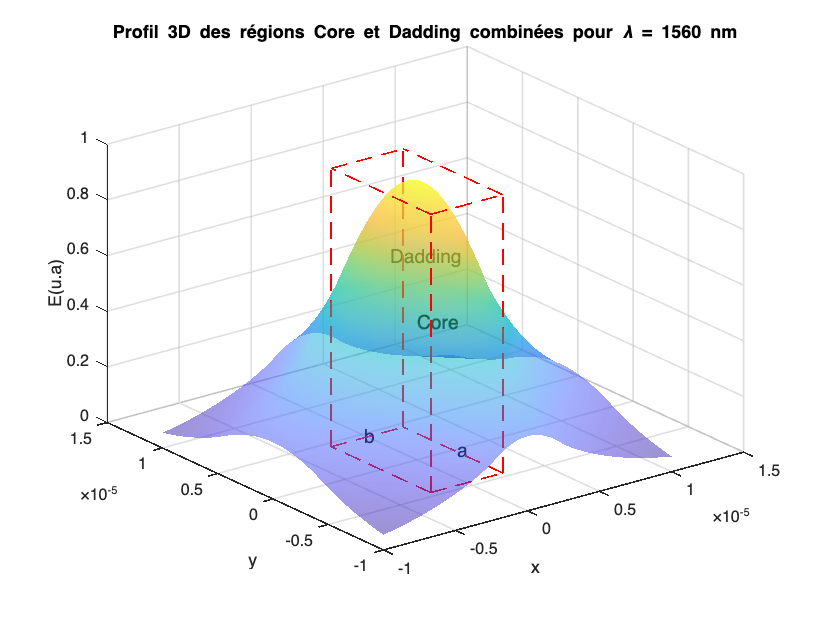


%%


% Pour LAMBDA2

% Génération de la grille 3D
[X, Y] = meshgrid(x, x);

% Initialisation de Z avec des zéros
Z2 = zeros(size(X));

% Conditions pour les régions Core, Dadding et chevauchantes
L_core = (abs(X) < b/2 & abs(Y) < a/2);
L_dadding_X1 = (abs(X) >= b/2 & abs(Y) < a/2);
L_dadding_X2 = (abs(X) >= b/2 & abs(Y) > a/2);
L_dadding_Y1 = (abs(Y) >= a/2 & abs(X) < b/2);
L_dadding_Y2 = (abs(Y) >= a/2 & abs(X) > b/2);

% Attribution des valeurs en fonction des conditions pour la région Core
Z2(L_core) = cos(alpha_h1560 * X(L_core)) .* cos(alpha_1560_v * Y(L_core));

% Calcul des valeurs pour la région Dadding en quatre parties
Z_dadding_X1 = cos(alpha_h1560*b/2)*exp(kappa_h1560*b/2) .* exp(-kappa_h1560*abs(X(L_dadding_X1))) .* cos(alpha_1560_v * Y(L_dadding_X1));
Z_dadding_X2 = cos(alpha_h1560*b/2)*exp(kappa_h1560*b/2) .* exp(-kappa_h1560*abs(X(L_dadding_X2))) .*cos(alpha_1560_v*a/2)* exp(kappa_h1560*a/2) .* exp(-kappa_h1560*abs(Y(L_dadding_X2)));

Z_dadding_Y1 = cos(alpha_1560_v*a/2)*exp(kappa_h1560*a/2) .* exp(-kappa_h1560*abs(Y(L_dadding_Y1))) .* cos(alpha_h1560 * X(L_dadding_Y1));
Z_dadding_Y2 = cos(alpha_1560_v*a/2)*exp(kappa_h1560*a/2) .* exp(-kappa_h1560*abs(Y(L_dadding_Y2))) .*cos(alpha_h1560*b/2)*exp(kappa_h1560*b/2) .* exp(-kappa_h1560*abs(X(L_dadding_Y2)));

% Attribution des valeurs calculées aux régions correspondantes
Z2(L_dadding_X1) = Z_dadding_X1;
Z2(L_dadding_X2) = Z_dadding_X2;
Z2(L_dadding_Y1) = Z_dadding_Y1;
Z2(L_dadding_Y2) = Z_dadding_Y2;

% Affichage de Z(L1) et Z(L2) combinés
figure;
surf(X, Y, Z2, 'FaceAlpha', 0.5, 'EdgeColor', 'none');
% Ajout du titre
title('Profil 3D des régions Core et Dadding combinées pour \lambda = 1560 nm');

% Ajout des étiquettes d'axe
xlabel('x');
ylabel('y');
zlabel('E(u.a)');

% Affichage du texte "Core" dans la zone Core
text(0, 0, 0.5, 'Core', 'FontSize', 12, 'Color', 'black');

% Affichage du texte "Dadding" dans la zone Dadding
text(b, a, 0.5, 'Dadding', 'FontSize', 12, 'Color', 'black');

% Affichage du côté a 
text(b/2+0.3e-6, 0, 0, 'a', 'FontSize', 12, 'Color', 'black');

% Affichage du côté a 
text(0, a/2+0.3e-6, 0, 'b', 'FontSize', 12, 'Color', 'black');

% Ajout des lignes en pointillés pour délimiter la zone du core
hold on;

line([-b/2, -b/2], [-a/2, -a/2], [0, 1], 'Color', 'red', 'LineStyle', '--');
line([b/2, b/2], [-a/2, -a/2], [0, 1], 'Color', 'red', 'LineStyle', '--');
line([-b/2, -b/2], [a/2, a/2], [0, 1], 'Color', 'red', 'LineStyle', '--');
line([b/2, b/2], [a/2, a/2], [0, 1], 'Color', 'red', 'LineStyle', '--');

line([-b/2, -b/2], [-a/2, a/2], [1, 1], 'Color', 'red', 'LineStyle', '--');
line([b/2, b/2], [-a/2, a/2], [1, 1], 'Color', 'red', 'LineStyle', '--');
line([-b/2, b/2], [-a/2, -a/2], [1, 1], 'Color', 'red', 'LineStyle', '--');
line([-b/2, b/2], [a/2, a/2], [1, 1], 'Color', 'red', 'LineStyle', '--');

line([-b/2, -b/2], [-a/2, a/2], [0, 0], 'Color', 'red', 'LineStyle', '--');
line([b/2, b/2], [-a/2, a/2], [0, 0], 'Color', 'red', 'LineStyle', '--');
line([-b/2, b/2], [-a/2, -a/2], [0, 0], 'Color', 'red', 'LineStyle', '--');
line([-b/2, b/2], [a/2, a/2], [0, 0], 'Color', 'red', 'LineStyle', '--');
hold off;

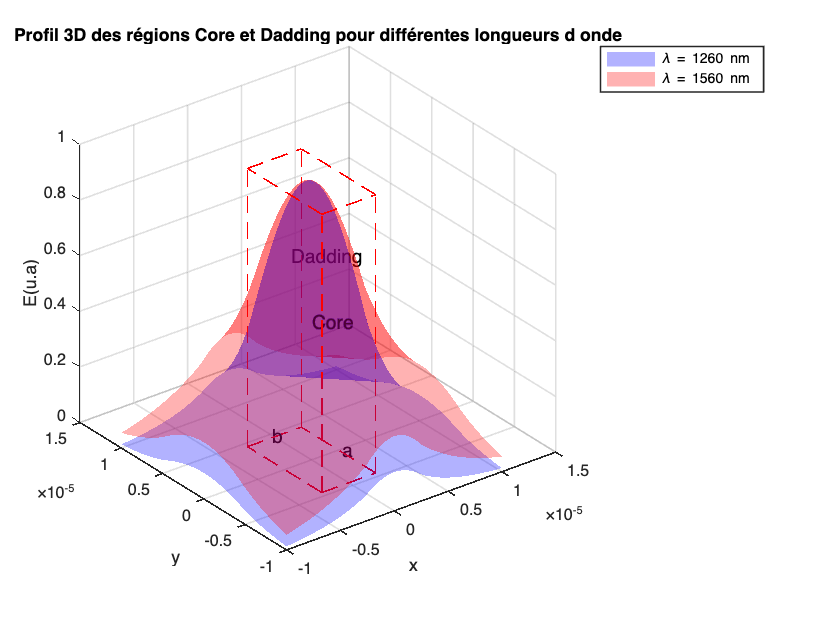


%%

% Superposition des differents LAMBDA

figure;
% Plot de Z1 avec une couleur
surf(X, Y, Z1, 'FaceAlpha', 0.3, 'EdgeColor', 'none', 'FaceColor', 'blue');
hold on;
% Plot de Z2 avec une autre couleur
surf(X, Y, Z2, 'FaceAlpha', 0.3, 'EdgeColor', 'none', 'FaceColor', 'red');
hold off;
% Ajout du titre à la figure
title('Profil 3D des régions Core et Dadding pour différentes longueurs d onde');

% Ajout des étiquettes d'axe
xlabel('x');
ylabel('y');
zlabel('E(u.a)');

% Ajout des légendes pour les différentes surfaces
legend('\lambda = 1260 nm', '\lambda = 1560 nm');

% Affichage du texte "Core" dans la zone Core
text(0, 0, 0.5, 'Core', 'FontSize', 12, 'Color', 'black');

% Affichage du texte "Dadding" dans la zone Dadding
text(b, a, 0.5, 'Dadding', 'FontSize', 12, 'Color', 'black');

% Affichage du côté a 
text(b/2+0.3e-6, 0, 0, 'a', 'FontSize', 12, 'Color', 'black');

% Affichage du côté a 
text(0, a/2+0.3e-6, 0, 'b', 'FontSize', 12, 'Color', 'black');

% Ajout des lignes en pointillés pour délimiter la zone du core
hold on;

% Lignes pointillées pour délimiter la zone du core sans légende
line([-b/2, -b/2], [-a/2, -a/2], [0, 1], 'Color', 'red', 'LineStyle', '--','HandleVisibility', 'off');
line([b/2, b/2], [-a/2, -a/2], [0, 1], 'Color', 'red', 'LineStyle', '--','HandleVisibility', 'off');
line([-b/2, -b/2], [a/2, a/2], [0, 1], 'Color', 'red', 'LineStyle', '--','HandleVisibility', 'off');
line([b/2, b/2], [a/2, a/2], [0, 1], 'Color', 'red', 'LineStyle', '--','HandleVisibility', 'off');

line([-b/2, -b/2], [-a/2, a/2], [1, 1], 'Color', 'red', 'LineStyle', '--','HandleVisibility', 'off');
line([b/2, b/2], [-a/2, a/2], [1, 1], 'Color', 'red', 'LineStyle', '--','HandleVisibility', 'off');
line([-b/2, b/2], [-a/2, -a/2], [1, 1], 'Color', 'red', 'LineStyle', '--','HandleVisibility', 'off');
line([-b/2, b/2], [a/2, a/2], [1, 1], 'Color', 'red', 'LineStyle', '--','HandleVisibility', 'off');

line([-b/2, -b/2], [-a/2, a/2], [0, 0], 'Color', 'red', 'LineStyle', '--','HandleVisibility', 'off');
line([b/2, b/2], [-a/2, a/2], [0, 0], 'Color', 'red', 'LineStyle', '--','HandleVisibility', 'off');
line([-b/2, b/2], [-a/2, -a/2], [0, 0], 'Color', 'red', 'LineStyle', '--','HandleVisibility', 'off');
line([-b/2, b/2], [a/2, a/2], [0, 0], 'Color', 'red', 'LineStyle', '--','HandleVisibility', 'off');
hold off;